# Lecture 12: Image Thresholding

# Part 3: Multiple Thresholding

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture12 - Image Thresholding

- pdf versions of the .mlx files are also available for those using GNU Octave

clearvars; close all; clc;

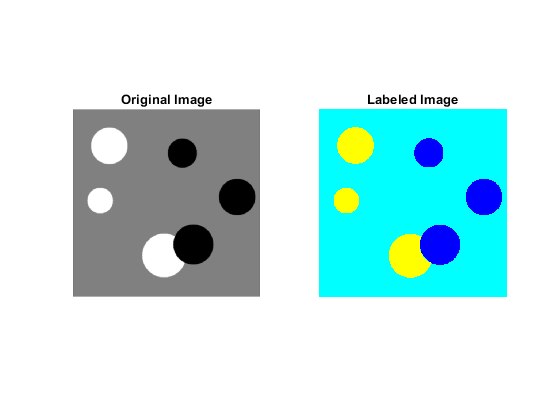

% read input image
I = imread('images/circlesBrightDark.png');
if(size(I,3) == 3) % convert to grayscale if needed
    I=rgb2gray(I); 
end

T = multithresh(I,2);
seg = imquantize(I,T);
RGBlabels = label2rgb(seg); 

% plot images
subplot(1,2,1), imshow(I), title('Original Image');
subplot(1,2,2), imshow(RGBlabels), title('Labeled Image');